clear all
Data_E3 = struct( ... % column: 1 = DC code/stress, 2 = norminal stress, 3 = cycle life time.
    'A',  [80, 216.3, 27700],...
    'B',  [90, 138.2, 151200],...
    'C1', [40, 65.7, 123500],...
    'C2', [80, 49.3, 2341000],...
    'C3', [56, 1.5, 10000000])

Data_E3 = struct with fields:
     A: [80 216.3 27700]
     B: [90 138.2 151200]
    C1: [40 65.7 123500]
    C2: [80 49.3 2341000]
    C3: [56 1.5 10000000]



Data_IIW = struct( ...
    'A',  [100 429.74 6900.2],... 
    'B',  [90.909 137.8 1.5723e+05],... 
    'C1', [61 90.15 1.6965e+05],... 
    'C2', [90 141 1.4241e+05],... 
    'C3', [100 54.116 3.4553e+06])

Data_IIW = struct with fields:
     A: [100 429.74 6900.2]
     B: [90.909 137.8 157230]
    C1: [61 90.15 169650]
    C2: [90 141 142410]
    C3: [100 54.116 3455300]




N_C = 2e6;
N_D = 1e7;
m1 = 3;
m2 = 5;
y_Mf = 1.54;

A location

format shortg

S_hs = 299.2;
S_k = 1236.4;

K_w = S_k / S_hs

K_w =        4.1324



FAT = 225;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    6.2376e+12


S_D = super(C1, N_D, sym('S'), m1)

S_D =        85.442



if  S_k > S_D
    N_life = super(C1, sym('N'), S_k, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_k, m2)
end

N_life =        3300.2



Data_IIW_notch = struct( ... % column: 1 = DC code/stress, 2 = norminal stress, 3 = cycle life time.
    'A', [FAT, S_k, N_life])

Data_IIW_notch = struct with fields:
    A: [225 1236.4 3300.2]


B location

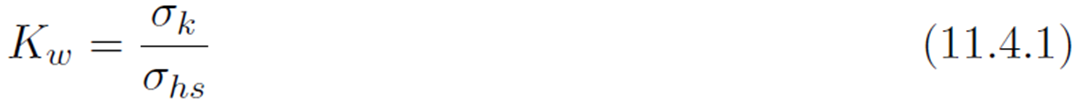

S_hs = 149;
S_k = 262.1;

K_w = S_k / S_hs

K_w =        1.7591



k_miss = 1.1;

ans =        204.55


FAT = 225 / k_miss;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    4.6833e+12


S_D = super(C1, N_D, sym('S'), m1)

S_D =        77.657



if  S_k > S_D
    N_life = super(C1, sym('N'), S_k, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_k, m2)
end

N_life =     2.601e+05



Data_IIW_notch.B = [FAT, S_k, N_life]

Data_IIW_notch = struct with fields:
    B: [204.5 262.1 2.601e+05]


C1 location root

format shortg

S_hs = 207; %? 5 ???
S_k = 377.1;

K_w = S_k / S_hs

K_w =        1.8217



FAT = 225;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    6.2376e+12


S_D = super(C1, N_D, sym('S'), m1)

S_D =        85.442



if  S_k > S_D
    N_life = super(C1, sym('N'), S_k, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_k, m2)
end

N_life =    1.1632e+05



Data_IIW_notch.C1 = [FAT, S_k, N_life]

Data_IIW_notch = struct with fields:
     A: [225 1236.4 3300.2]
     B: [204.5 262.1 2.601e+05]
    C1: [225 377.1 1.1632e+05]


C2 location toe

format shortg

S_hs = 140.5;
S_k = 580.9;

K_w = S_k / S_hs

K_w =        4.1345



FAT = 225;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    6.2376e+12


S_D = super(C1, N_D, sym('S'), m1)

S_D =        85.442



if  S_k > S_D
    N_life = super(C1, sym('N'), S_k, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_k, m2)
end

N_life =         31821



Data_IIW_notch.C2 = [FAT, S_k, N_life]

Data_IIW_notch = struct with fields:
     A: [225 1236.4 3300.2]
     B: [204.5 262.1 2.601e+05]
    C1: [225 377.1 1.1632e+05]
    C2: [225 580.9 31821]


C3 location toe

format shortg

S_hs = 36.6;
S_k = 206.4;

K_w = S_k / S_hs

K_w =        5.6393



FAT = 225;

C1 = super(sym('C'), N_C, FAT, m1, y_Mf)

C1 =    6.2376e+12


S_D = super(C1, N_D, sym('S'), m1)

S_D =        85.442



if  S_k > S_D
    N_life = super(C1, sym('N'), S_k, m1)
else
    C2 = super(sym('C'), N_D, S_D, m2)
    N_life = super(C2, sym('N'), S_k, m2)
end

N_life =    7.0939e+05



Data_IIW_notch.C3 = [FAT, S_k, N_life]

Data_IIW_notch = struct with fields:
     A: [225 1236.4 3300.2]
     B: [204.5 262.1 2.601e+05]
    C1: [225 377.1 1.1632e+05]
    C2: [225 580.9 31821]
    C3: [225 206.4 7.0939e+05]


Data_IIW

Data_IIW = struct with fields:
     A: [100 429.74 6900.2]
     B: [90.909 137.8 157230]
    C1: [61 90.15 169650]
    C2: [90 141 142410]
    C3: [100 54.116 3455300]


Data_E3

Data_E3 = struct with fields:
     A: [80 216.3 27700]
     B: [90 138.2 151200]
    C1: [40 65.7 123500]
    C2: [80 49.3 2341000]
    C3: [56 1.5 10000000]


Data_IIW_notch

Data_IIW_notch = struct with fields:
     A: [225 1236.4 3300.2]
     B: [204.5 262.1 2.601e+05]
    C1: [225 377.1 1.1632e+05]
    C2: [225 580.9 31821]
    C3: [225 206.4 7.0939e+05]


datas_E3 = [Data_E3.A; Data_E3.B; Data_E3.C1; Data_E3.C2; Data_E3.C3]

datas_E3 =            80        216.3        27700
           90        138.2    1.512e+05
           40         65.7    1.235e+05
           80         49.3    2.341e+06
           56          1.5        1e+07


datas_IIW = [Data_IIW.A; Data_IIW.B; Data_IIW.C1; Data_IIW.C2; Data_IIW.C3]

datas_IIW =           100       429.74       6900.2
       90.909        137.8   1.5723e+05
           61        90.15   1.6965e+05
           90          141   1.4241e+05
          100       54.116   3.4553e+06


datas_IIW_notch = [Data_IIW_notch.A; Data_IIW_notch.B; Data_IIW_notch.C1; Data_IIW_notch.C2; Data_IIW_notch.C3]

datas_IIW_notch =           225       1236.4       3300.2
        204.5        262.1    2.601e+05
          225        377.1   1.1632e+05
          225        580.9        31821
          225        206.4   7.0939e+05


for i = 1:5
    N_IIW(i) = datas_IIW(i,3);
    N_E3(i) = datas_E3(i,3);
    N_IIW_notch(i) = datas_IIW_notch(i,3);
    Ss_IIW(i) = datas_IIW(i,2);
    Ss_E3(i) = datas_E3(i,2);
    Ss_IIW_notch(i) = datas_IIW_notch(i,2);
end

K_ws = Ss_IIW_notch ./ Ss_IIW;
K_ws'

ans =        2.8771
        1.902
        4.183
       4.1199
        3.814



tab = table([N_IIW; N_E3; N_IIW_notch; Ss_IIW; Ss_E3; Ss_IIW_notch]', ...
    RowNames={'A', 'B', 'C1', 'C2', 'C3'})%,...

tab = 5×1 table
             Var1   
          __________

    A     1×6 double
    B     1×6 double
    C1    1×6 double
    C2    1×6 double
    C3    1×6 double


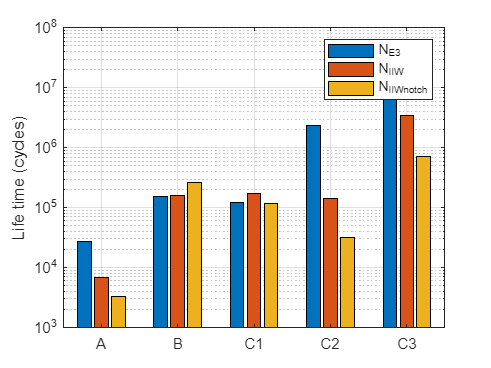

    % VariableNames={'N_IIW', 'N_E3', 'S_IIW', 'S_E3', 'last'})


figure
bar_data = [N_E3' N_IIW' N_IIW_notch'];
bar(bar_data)
% Sætter y-aksen til logaritmisk skala
set(gca, 'YScale', 'log');
ylim([1e3 1e8]);
xticks(1:length(N_IIW)); % Sørg for, at der er lige så mange tick-mærker som data-punkter
xticklabels({'A', 'B', 'C1', 'C2', 'C3'}); % Tilpas x-aksen labels
ylabel('Life time (cycles)')

% Tilføj grid for bedre læsbarhed
grid on;
legend('N_E3', 'N_IIW', 'N_IIW_notch')

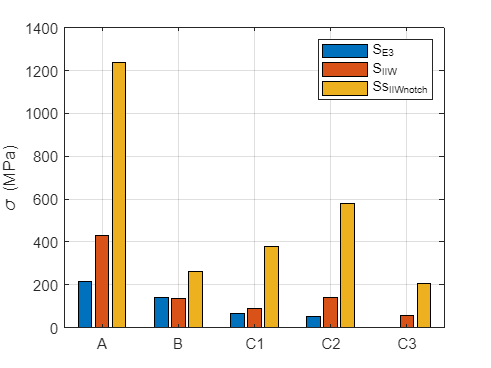



figure
bar_data = [Ss_E3', Ss_IIW', Ss_IIW_notch'];
bar(bar_data)
xticks(1:length(Ss_IIW)); % Sørg for, at der er lige så mange tick-mærker som data-punkter
xticklabels({'A', 'B', 'C1', 'C2', 'C3'}); % Tilpas x-aksen labels
ylabel('\sigma_R (MPa)')

% Tilføj grid for bedre læsbarhed
grid on;
legend('S_E3', 'S_IIW', 'Ss_IIW_notch')